# Distortion, noise, and strain

Just like DNaS_5.mlx but the displayed units and conversions are now modifiable. Plus, there are some other changes in comparing the defined and calculated strain. The lambdaChoose() function was redacted due to impracticality.

Let's define the initial parameters. If new to this live script, I suggest you change the values here and here only.

#### Image specifications

image_length = 1024; % [pixel]
image_height = 1024; % [pixel]

units = "nm";
conversion_factor = 5.6236/0.369; % [pixel/units]

lattice_constant = 0.369; % [units]        NOTE: [lc] = [latice constant]
elevation_amplitude = 1/24; % [lc]

Q_1 = [1 1]; % [lc^-1]
crystal = "square";

lambda = 0.2; % [lc^-1]
confidence_level = 0.99;

#### Distortion, noise, and strain parameters

distortion_type = "poly33";

distortion_stdMagnitude = 2; % empirically found
%{
    if "poly33", this is the distortion std magnitude per coefficient times
    the image_length(height)/32
    if "custom", this is the distortion std maximum magnitude times
    image_length(height)/64 for drift and image_length(height)/256 for
    hysteresis and creep
%}

noise_minimumLength = 0.15; % [lc]
noise_stdMagnitude = 1/32; % [lc]

secnoise_minimumLength = 30; % [lc]
secnoise_stdMagnitude = 1/24; % [lc]

strain_minimumLength = 0.5; % [lc]
strain_stdMagnitude = 1/384*0; % [lc]

#### Pre-processing

Processing the inputs, converting units. You probably would't want to edit these.

cf = conversion_factor;
lc = lattice_constant*cf;
zscore = zscorer(confidence_level);
lambda = lambda/lc;


disp("image height = " + image_height/cf + " ["+units+"], " + ...
    image_height + " [px]")

image height = 67.1911 [nm], 1024 [px]


disp("image length = " + image_length/cf + " ["+units+"], " + ...
    image_length + " [px]")

image length = 67.1911 [nm], 1024 [px]


disp("lattice constant = " + lattice_constant + " ["+units+"], " + ...
    lc + " [px]");

lattice constant = 0.369 [nm], 5.6236 [px]


disp("elevation amplitude: " + elevation_amplitude + " [lc]");

elevation amplitude: 0.041667 [lc]


disp("crystal structure: " + crystal);

crystal structure: square


disp("Lambda used = " + lambda*lc + " [lc^-1]");

Lambda used = 0.2 [lc^-1]



Q_1 = Q_1.';
if crystal == "square"
    Q_1 = Q_1 * 2*pi / (norm(Q_1)*lc);
    rot = [0 -1; 1 0];
    Q_2 = rot*Q_1;
    Qbragg = [Q_1 Q_2];
elseif crystal == "hexagonal"
    Q_1 = Q_1 * 2*pi / (norm(Q_1)*lc*(sqrt(3)/2));
    rot = [-1/2 -sqrt(3)/2; sqrt(3)/2 -1/2];
    Q_2 = rot*Q_1;
    Q_3 = rot*Q_2;
    Qbragg = [Q_1 Q_2 Q_3];
else
    disp("Custom lattice. Bragg wavevectors must be specified.")
end

for ctr = 1:size(Qbragg,2)
    disp("Q_" + ctr + " = (" + Qbragg(1,ctr)/(2*pi)*cf + ", " + ...
        Qbragg(2,ctr)/(2*pi)*cf + ") ["+units+"^-1]");
end

Q_1 = (1.9163, 1.9163) [nm^-1]
Q_2 = (-1.9163, 1.9163) [nm^-1]



if distortion_type == "poly33"
    disp("Poly33 coefficients:   p00 p10 p01 p20 p11 p02 p30 p21 p12 p03");

    % 0 as p00 to eliminate phase shifts
    dparams      = [0 randn(1,9)] * image_length/32   /9*distortion_stdMagnitude;
    dparams(2,:) = [0 randn(1,9)] * image_height/32   /9*distortion_stdMagnitude;

    disp("x component [all in a.u.]");
    fprintf("%.1f  ",dparams(1,:));
    disp("y component [all in a.u.]");
    fprintf("%.1f  ",dparams(2,:));

elseif distortion_type == "custom"
    drift      =  max(image_length,image_height)/64*randn(1,2); % [lc/scan]
    hysteresis =  max(image_length,image_height)/256*randn(1,2); % [lc]
    creep      =  max(image_length,image_height)/256*randn(1,2); % [lc]
    dparams = [drift hysteresis creep]*distortion_stdMagnitude;

    disp("drift      = ("+drift(1)+","+drift(2)+") [lc/scan]");
    disp("hysteresis = ("+hysteresis(1)+","+hysteresis(2)+") [lc]");
    disp("creep      = ("+creep(1)+","+creep(2)+") [lc]");
end

Poly33 coefficients:   p00 p10 p01 p20 p11 p02 p30 p21 p12 p03


x component [all in a.u.]


0.0  -6.2  -8.5  -13.6  15.5  1.0  1.1  6.7  4.0  7.7  

y component [all in a.u.]


0.0  -19.0  2.0  7.4  7.6  15.7  8.0  -7.1  7.3  -12.7  


disp("noise minimum length = "+noise_minimumLength+" [lc]; " + ...
    "noise magnitude (std) = "+noise_stdMagnitude+" [lc]");

noise minimum length = 0.15 [lc]; noise magnitude (std) = 0.03125 [lc]



disp("secnoise minimum length = "+secnoise_minimumLength+" [lc]; " + ...
    "secnoise magnitude (std) = "+secnoise_stdMagnitude+" [lc]");

secnoise minimum length = 30 [lc]; secnoise magnitude (std) = 0.041667 [lc]



disp("strain minimum length = "+strain_minimumLength+" [lc]; " + ...
    "strain magnitude (std) = "+strain_stdMagnitude+" [lc]");

strain minimum length = 0.5 [lc]; strain magnitude (std) = 0 [lc]


## 1    Creating a distorted and noisy lattice with local physical strain

The perfect square lattice is distorted according to the Lawler et al. (2010) paper with an atom centered at the origin (0,0) — matrix indices (1,1) for MATLAB. Noise is added to the lattice created above with an average magnitude and undulation length specified in the first code cell.

### Adding non-local distortions, random elevation noise, and local "physical strain"

u = uCreate(image_height,image_length,lc, ...
    distortion_type,dparams);

noise = noiseCreate(image_height,image_length,lc, ...
    noise_minimumLength,noise_stdMagnitude);

secnoise = noiseCreate(image_height,image_length,lc, ...
    secnoise_minimumLength,secnoise_stdMagnitude);

cstrain = strainCreate(image_height,image_length,lc, ...
    strain_stdMagnitude,strain_minimumLength);

noise = noise + secnoise;
u = u + cstrain;

### Creating and plotting the image and its Fourier transform

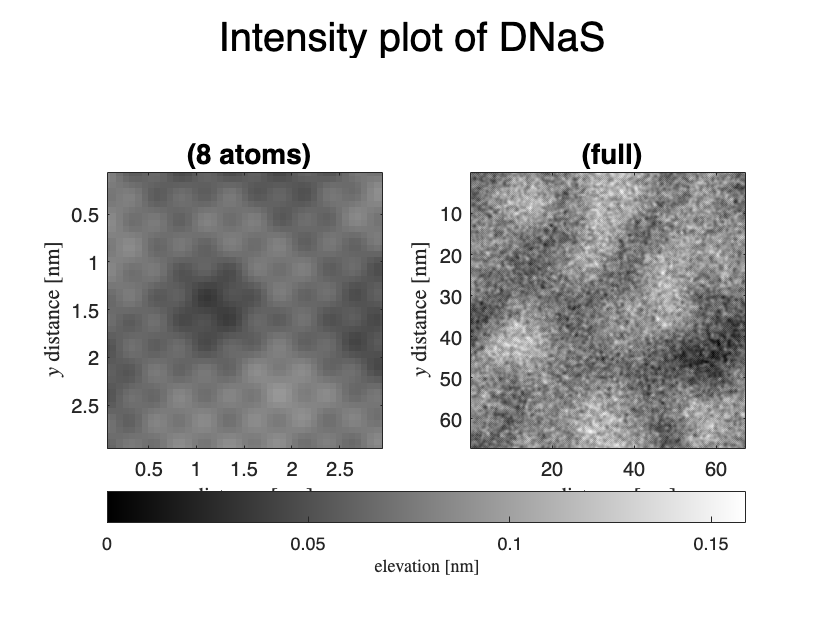

lattice = uTransform(u,Qbragg)*lc*elevation_amplitude; 
% check the sign of u in uTransform()
% notice that the elevation variation is only 1/24 of the lattice constant

lattice = lattice+noise;

% to make zero the lowest value
lattice = lattice - min(lattice,[],"all");

comboPlot(lattice,"DNaS",lc,units=units,cf=cf);

myFFT(lattice,"DNaS",cscale='linear',defbragg=Qbragg, ...
    units=units,cf=cf,cunits=units,ccf=cf);

myFFT() estimates that the 2D lattice is perfect square.


## 3    Calculating total distortion

Using the Lawler-Fujita algorithm, the total distortion as the sum of the imaging distortion and the physical strain, $\vec{u}_{calc}=\vec{d}+\vec{s}$, is calculated. The effects of noise and the magnitude and type of tolerable distortion could be studied using the previous and the following code.

BranchCuts: No residues, length(rowres)=0; sum(abs(residue_charge))=0; sum(abs(residue_charge_masked))=0
BranchCuts: No residues, length(rowres)=0; sum(abs(residue_charge))=0; sum(abs(residue_charge_masked))=0


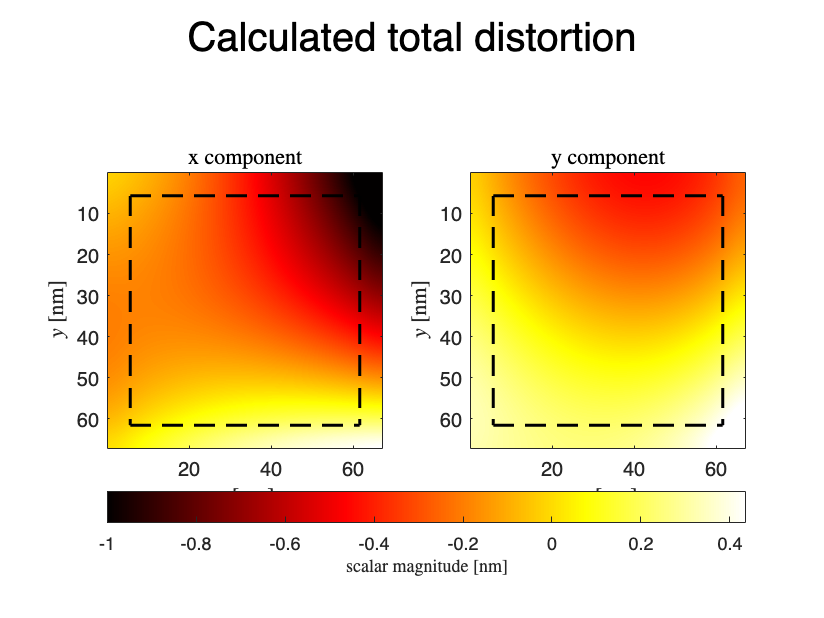

ucalc = myConv(lattice,Qbragg,lambda,zscore,units=units,cf=cf,cunits=units,ccf=cf);


uComboPlot(u,ucalc,lambda,zscore,units=units,cf=cf,cunits=units,ccf=cf);


if image_length-2*ceil(zscore/lambda)<=0 && image_height-2*ceil(zscore/lambda)<=0
    error("ERROR! No pixels without padded zeros remain.");
else
    npixel = (image_length-2*ceil(zscore/lambda))*(image_height-2*ceil(zscore/lambda));
    % the number of pixels averaged
    disp("Number of pixels averaged: " + npixel + " (" + ...
        npixel/(image_length*image_height)*100 + "%)");
end

Number of pixels averaged: 725904 (69.2276%)



[meanErr, stdErr] = uCompare(u,ucalc,lambda,zscore);
disp("Error is: " + meanErr + "+/-" + stdErr*zscore);

Error is: 0.0044588+/-0.00542


disp("Total error is: " + (meanErr+stdErr*zscore));

Total error is: 0.0098788


disp("Errors are relative unless stated otherwise.");

Errors are relative unless stated otherwise.


## 4    Undistorting the image

We undistort the image using my own undistort() function that in turn uses the imwarpConverse() function that I also built.

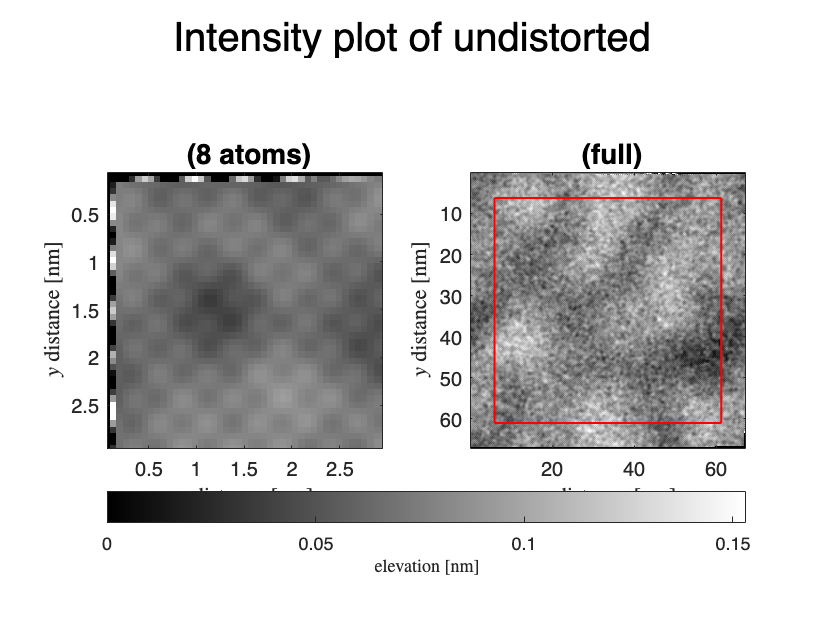

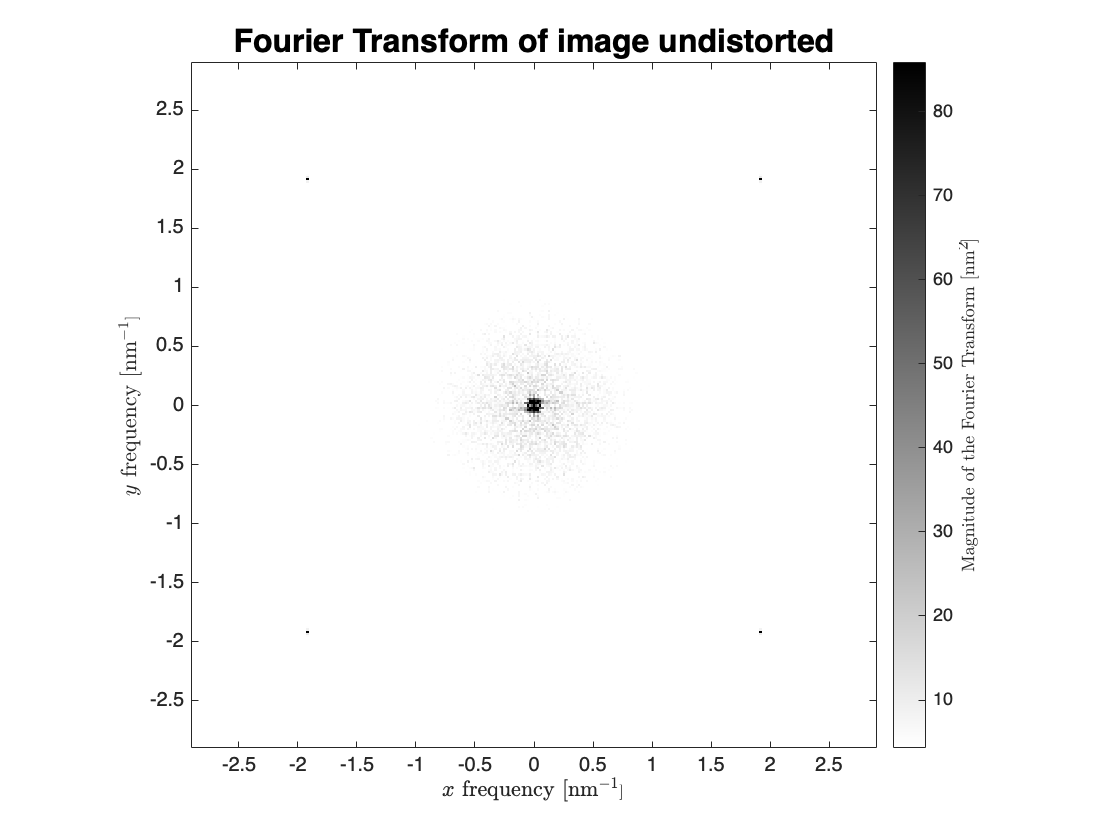

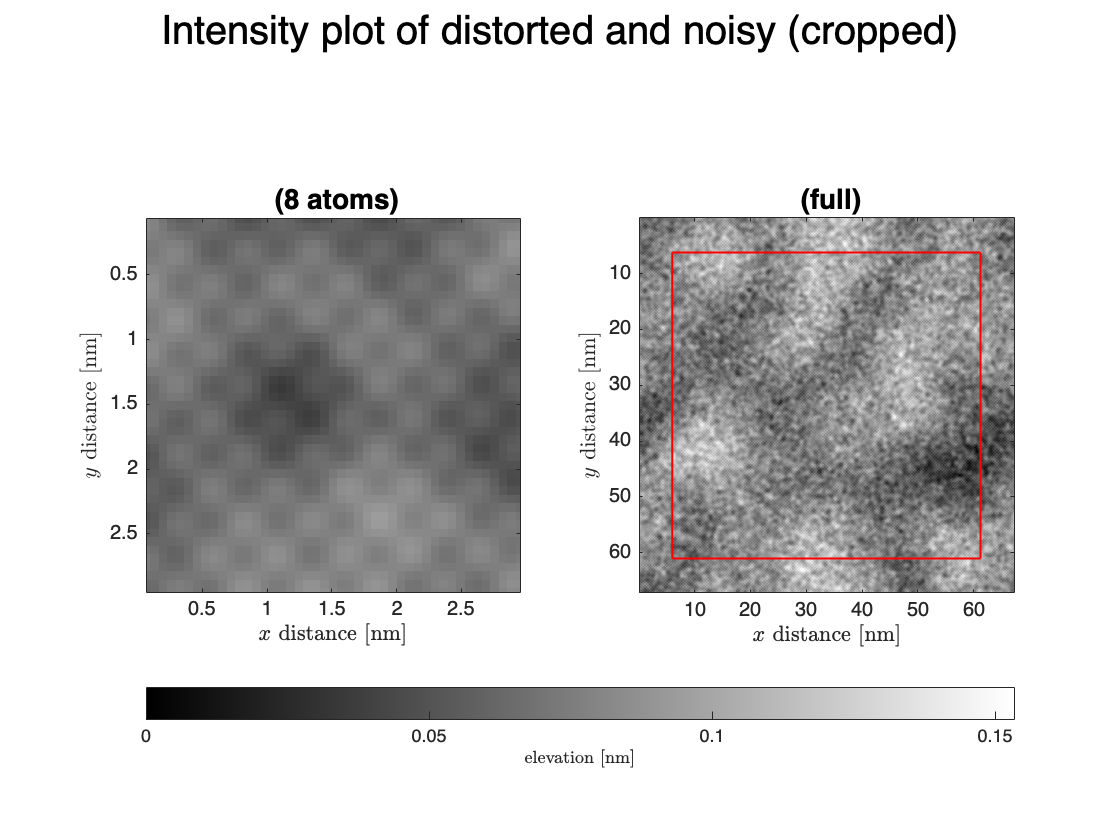

ulattice = undistort(lattice,-ucalc,lc,lambda,zscore, ...
    cscale='linear',linecuts=true,cryst_struct=crystal, ...
    units=units,cf=cf,cunits=units,ccf=cf);

## 5    Calculating physical strain

From the equation given above, the physical strain can be obtained by subtracting the smooth, third-digree polynomial imaging distortion from the total distortion. Or at least, that's the result according to Gao et al. (2017).

rot_angle = 0;
[fitresultx, gofx,outputx] = createFit(ucalc(:,:,1), lambda,zscore, rot_angle=rot_angle);

Doing polynomial fit using MATLAB's poly33.


[fitresulty, gofy,outputy] = createFit(ucalc(:,:,2), lambda,zscore, rot_angle=rot_angle);

Doing polynomial fit using MATLAB's poly33.


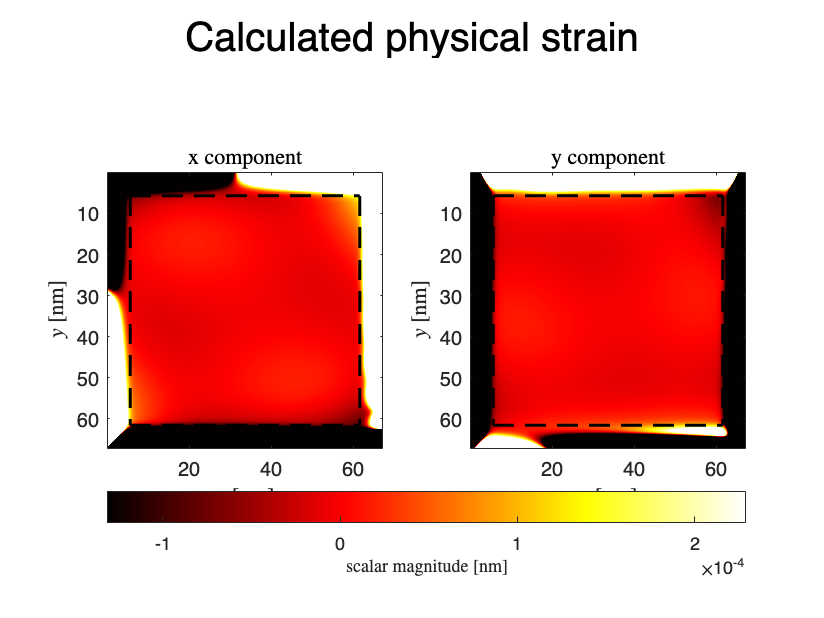


% to adjust for the [0,1] range of coordinates x,y,t
% and to avoid 'bad equation condition' warning
[xi,yi] = meshgrid(0:1/image_length:(image_length-1)/image_length ...
    ,0:1/image_height:(image_height-1)/image_height);
[xi,yi] = rotateMeshgrid(xi,yi,rot_angle);

strain = zeros(size(ucalc));
strain(:,:,1) = ucalc(:,:,1)-fitresultx(xi,yi);
strain(:,:,2) = ucalc(:,:,2)-fitresulty(xi,yi);

convPlot(strain(:,:,1),"Calculated physical strain",strain(:,:,2),lambda,zscore, ...
    units=units, cf=cf, cunits=units, ccf=cf);

The strain and it's first order partial derivatives are calculated and plotted. Biaxial and approximate uniaxial strain maps are also generated from the preceeding calculations.

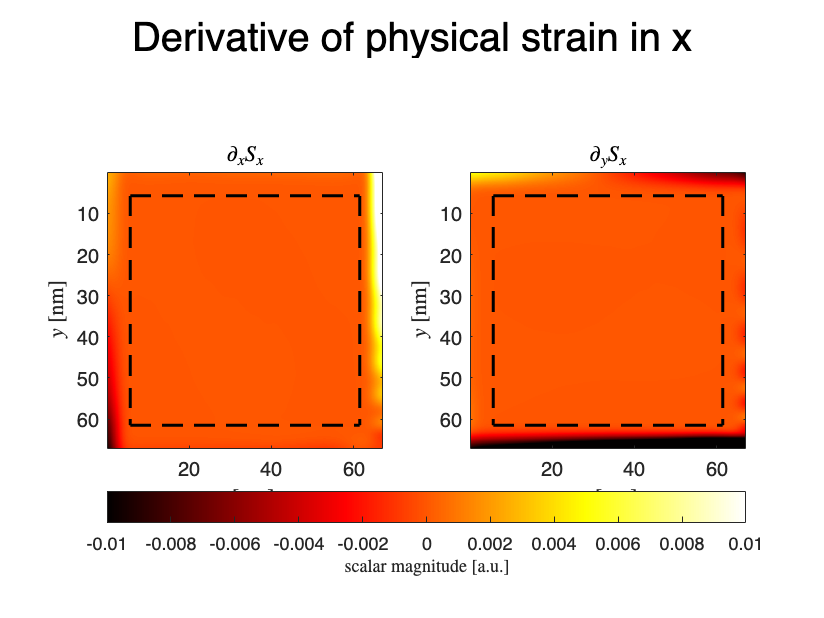

Sxdx = diff(strain(1:end-1,:,1),1,2);
Sxdy = diff(strain(:,1:end-1,1));
Sydx = diff(strain(1:end-1,:,2),1,2);
Sydy = diff(strain(:,1:end-1,2));
biaxial = (Sxdx+Sydy)/2;
uniaxial = (Sxdx-Sydy)/2;

climits_strain = [-1 1]*1e-2;
convPlot(Sxdx,["Derivative of physical strain in x", ...
    "$\partial_xS_x$","$\partial_yS_x$"],Sxdy,lambda,zscore, ...
    units=units,cf=cf,cunits="a.u.",ccf=1, climits=climits_strain);

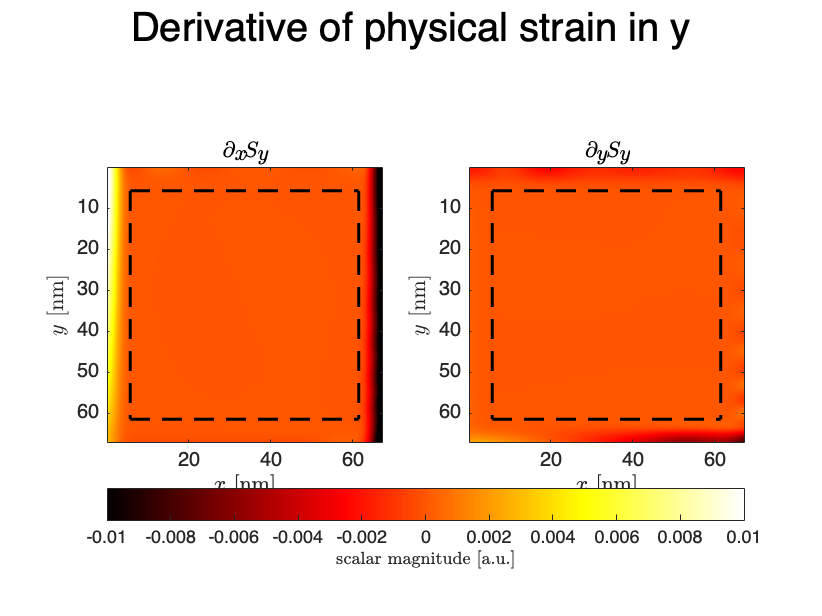

convPlot(Sydx,["Derivative of physical strain in y", ...
    "$\partial_xS_y$","$\partial_yS_y$"],Sydy,lambda,zscore, ...
    units=units,cf=cf,cunits="a.u.",ccf=1, climits=climits_strain);

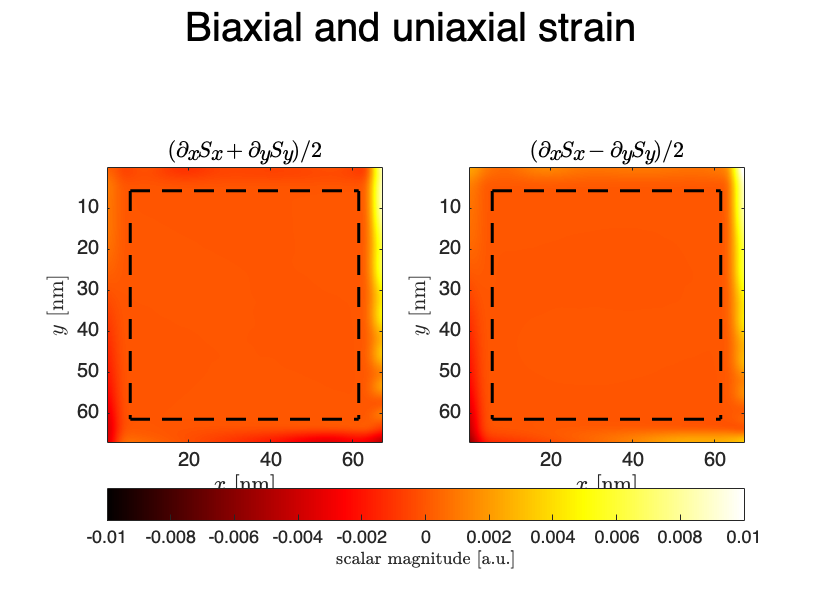

convPlot(biaxial,["Biaxial and uniaxial strain", ...
    "$(\partial_xS_x+\partial_yS_y)/2$", "$(\partial_xS_x-\partial_yS_y)/2$"], ...
    uniaxial,lambda,zscore, units=units,cf=cf,cunits="a.u.",ccf=1, ...
    climits=climits_strain);


[bmean, bstd] = uCompare(Sxdx,Sydy,lambda,zscore);
[umean, ustd] = uCompare(Sxdx,-Sydy,lambda,zscore);
disp("biaxial mean = " + bmean + " [a.u]");

biaxial mean = 4.1823e-07 [a.u]


disp("biaxial std = " + bstd + " [a.u]");

biaxial std = 4.8503e-06 [a.u]


disp("uniaxial mean = " + umean + " [a.u]");

uniaxial mean = -1.4038e-09 [a.u]


disp("uniaxial std = " + ustd + " [a.u]");

uniaxial std = 5.1171e-06 [a.u]


## 6    Correlation of calculated strain maps and elevation variations

b_r = uCompare(noise,biaxial,lambda,zscore);
u_r = uCompare(noise,uniaxial,lambda,zscore);
disp("biaxial vs noise regression, r^2 = " + b_r^2);

biaxial vs noise regression, r^2 = 1.1143e-06


disp("uniaxial vs noise regression, r^2 = " + u_r^2);

uniaxial vs noise regression, r^2 = 1.4388e-06
